# Assignment B

## Set up

clear all;
close all;
clc;
load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix



%% State space representation
syms f_theta1 f_theta2 f_theta3 f_u1 f_u2 theta1 omega1 theta2 omega2 theta3 omega3
syms u1 u2 y1 y2 y3 %b_1 b_2 b_3 J_1 k_1 k_2
x = [theta1 omega1 theta2 omega2 theta3 omega3].';
u = [u1 u2].';
y = [y1 y2 y3].';
f = [f_theta1 f_theta2 f_theta3 f_u1 f_u2].';
A = [0, 1, 0, 0, 0, 0;
     -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0;
     0, 0, 0, 1, 0, 0;
     k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0;
     0, 0, 0, 0, 0, 1;
     0, 0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];
B = [0 0
     1/J_1 0
     0 0
     0 1/J_1
     0 0
     0 0];
C = [1 0 0 0 0 0
     0 0 1 0 0 0
     0 0 0 0 1 0];
D = [0];
E_x = [0 -1/J_1 0 0 0 0].';
E_x2 = [0 0 0 0 0 0].';
E_y = zeros(3,1);
F_x = [zeros(6, 3), B];
F_y = [eye(3) zeros(3, 2)];

ThreeDiskSystem = ss(A,B,C,D);
disp(ThreeDiskSystem)

  3×2 ss array with properties:

                A: [6×6 double]
                B: [6×2 double]
                C: [3×6 double]
                D: [3×2 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {6×1 cell}
        StatePath: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [3×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



% ThreeDiskSystem.InputName = {'r';'fs'};

## Question 9

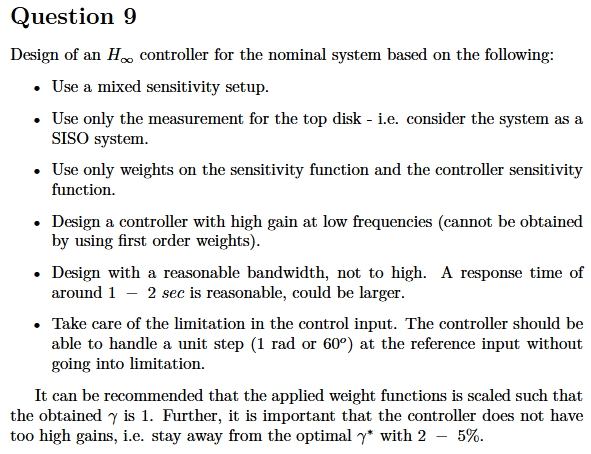

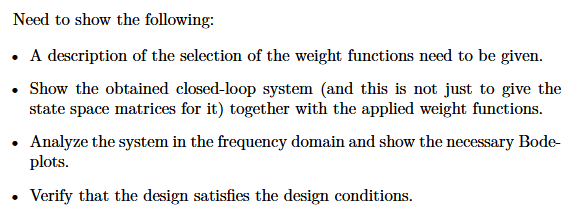

s = tf('s');
M = 3; A = 10^-4; omega_B = 4/1.5;

We = (s/M+omega_B)/(s+omega_B*A);   % W_1*S
Wu = (s*12+6)/(s+20);               % W_2*K*S
Wy = [];                            % W_3*T

ThreeDiskSystem.InputName = {'u1';'u2'};
ThreeDiskSystem.OutputName = {'y1';'y2';'y3'};

G = ThreeDiskSystem('y3', 'u1');

[K_inf,CL,gamma] = mixsyn(G, We^3, Wu, Wy);
fprintf('γ(gamma) = %.4f\n', gamma);

γ(gamma) = 1.3002


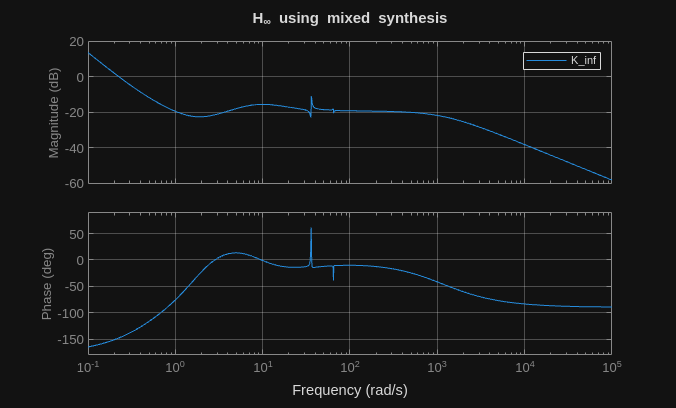

% Bode plot
figure(1)
bode(K_inf)
grid on
title('H_{\infty} using mixed synthesis')
legend()

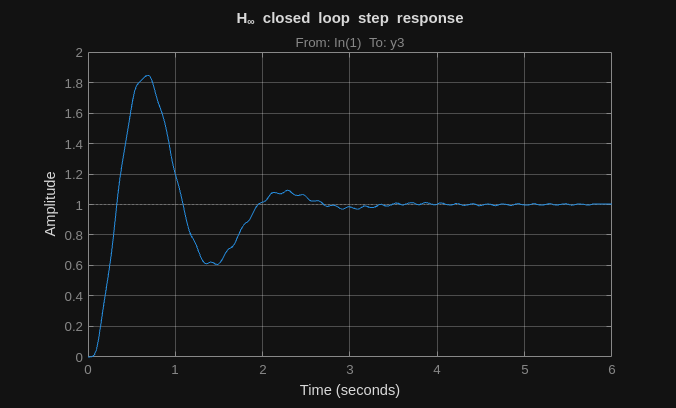

T_inf = feedback(G*K_inf, 1);
step(T_inf)
grid on
title('H_{\infty} closed loop step response')

## Question 10

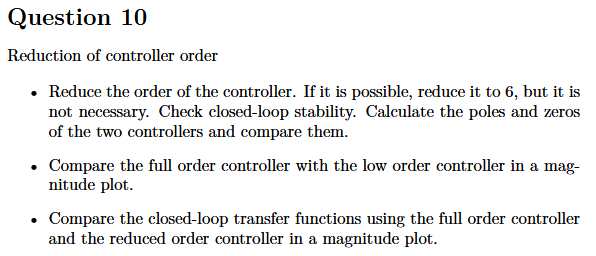

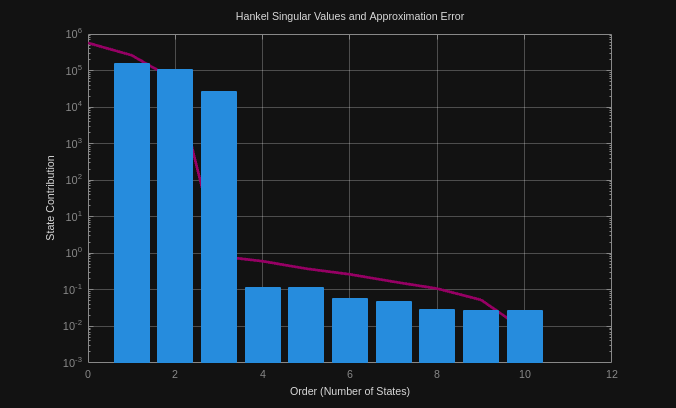

R = reducespec(K_inf, "Balanced");
view(R)

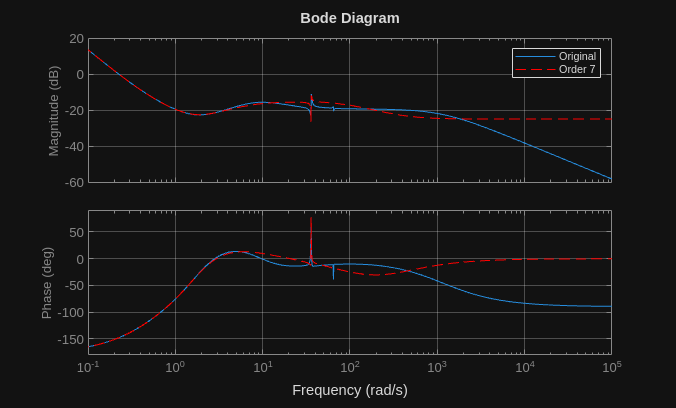

order = 7;
K_reduced = getrom(R, Order=order);
bode(K_inf, K_reduced, 'r--')
grid on
legend("Original", sprintf("Order %d", order))

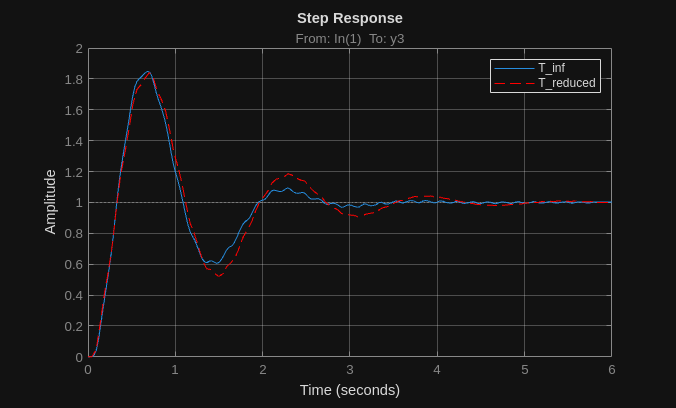

T_reduced = feedback(G*K_reduced, 1);
step(T_inf,T_reduced,'r--')
grid on
legend()

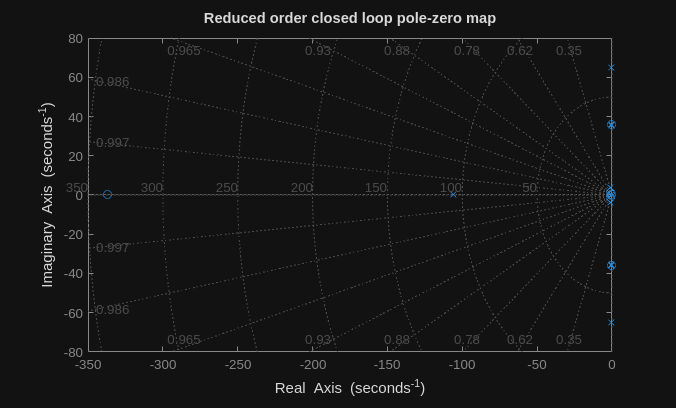

figure()
pzmap(T_reduced)
title("Reduced order closed loop pole-zero map")
grid on

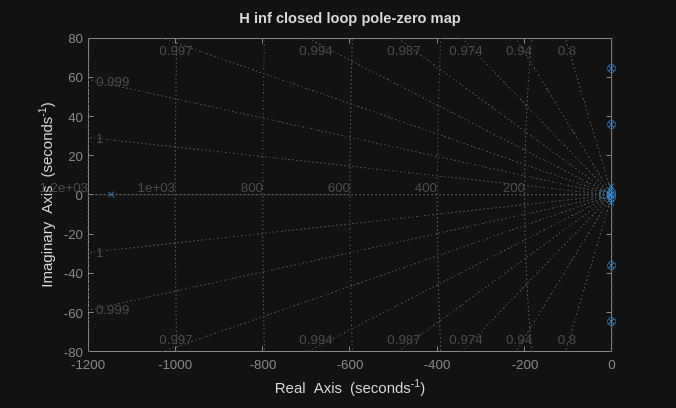

figure()
pzmap(T_inf)
title("H inf closed loop pole-zero map")
grid on

disp(zero(T_reduced))

   1.0e+02 *

  -3.3687 + 0.0000i
  -0.0008 + 0.3579i
  -0.0008 - 0.3579i
  -0.0127 + 0.0117i
  -0.0127 - 0.0117i
  -0.0000 + 0.0000i
  -0.0053 + 0.0000i



disp(pole(T_reduced))

   1.0e+02 *

  -1.0604 + 0.0000i
  -0.0010 + 0.6478i
  -0.0010 - 0.6478i
  -0.0051 + 0.3531i
  -0.0051 - 0.3531i
  -0.0006 + 0.3587i
  -0.0006 - 0.3587i
  -0.0097 + 0.0397i
  -0.0097 - 0.0397i
  -0.0197 + 0.0123i
  -0.0197 - 0.0123i
  -0.0000 + 0.0000i
  -0.0053 + 0.0000i



disp(zero(T_inf))

  -0.1211 +64.6931i
  -0.1211 -64.6931i
  -0.3083 +35.7447i
  -0.3083 -35.7447i
 -20.0000 + 0.0000i
  -1.3243 + 1.2222i
  -1.3243 - 1.2222i
  -0.0000 + 0.0000i
  -0.5319 + 0.0000i



disp(pole(T_inf))

   1.0e+03 *

  -1.1473 + 0.0000i
  -0.0001 + 0.0647i
  -0.0001 - 0.0647i
  -0.0001 + 0.0647i
  -0.0001 - 0.0647i
  -0.0003 + 0.0357i
  -0.0003 - 0.0357i
  -0.0003 + 0.0357i
  -0.0003 - 0.0357i
  -0.0017 + 0.0041i
  -0.0017 - 0.0041i
  -0.0034 + 0.0021i
  -0.0034 - 0.0021i
  -0.0038 + 0.0000i
  -0.0000 + 0.0000i
  -0.0005 + 0.0000i



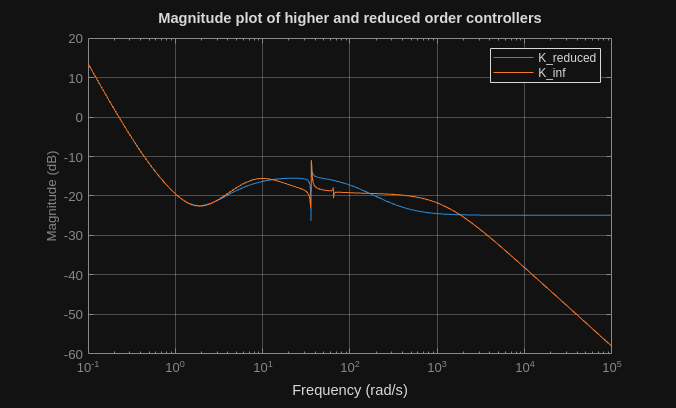

bodemag(K_reduced, K_inf)
legend()
grid on
title('Magnitude plot of higher and reduced order controllers')

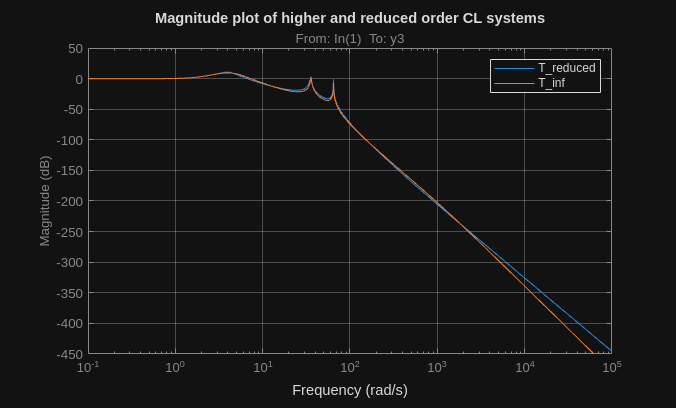

bodemag(T_reduced, T_inf)
legend()
grid on
title('Magnitude plot of higher and reduced order CL systems')

## Question 11

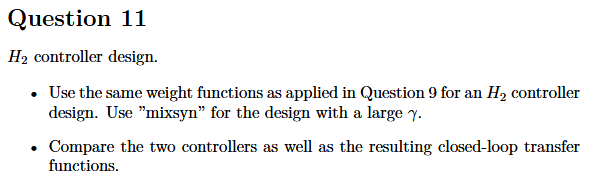

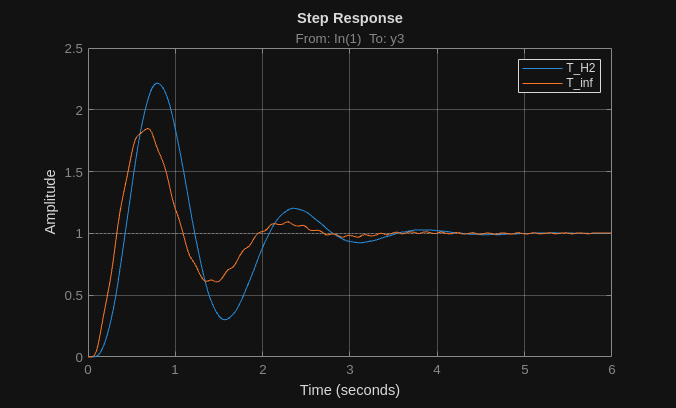

[K_H2, ~, ~] = mixsyn(G, We^3, Wu, Wy, 150);

T_H2 = feedback(G*K_H2, 1);
figure()
step(T_H2, T_inf)
grid on
legend()

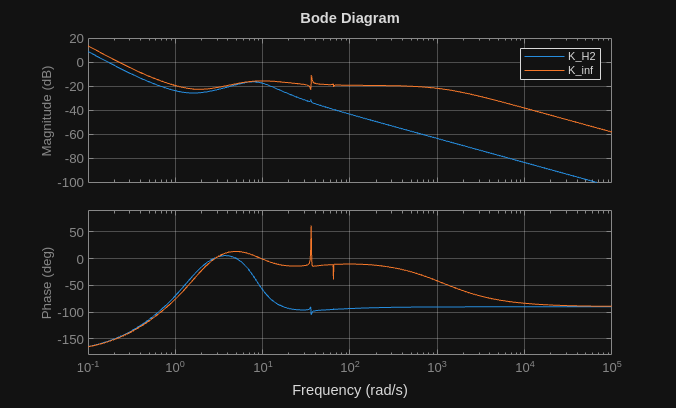

figure()
bode(K_H2, K_inf)
grid on
legend()

## Question 12

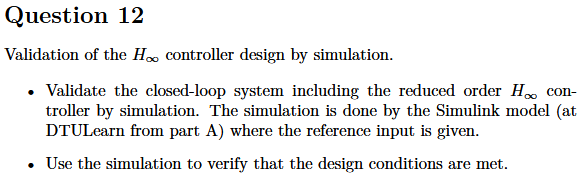

## Question 13

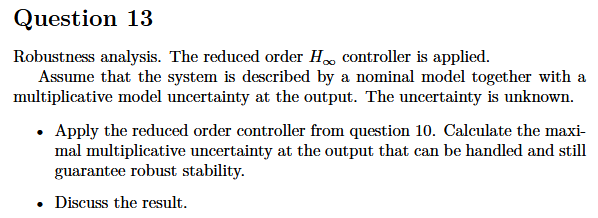

gamma_T = tf(hinfnorm(T_reduced), 1)


gamma_T =
 
  3.443
 
Static gain.
Model Properties


max_delta = tf(1/gamma_T, 1) % maximum allowable multiplicative uncertainty


max_delta =
 
  0.2904
 
Static gain.
Model Properties


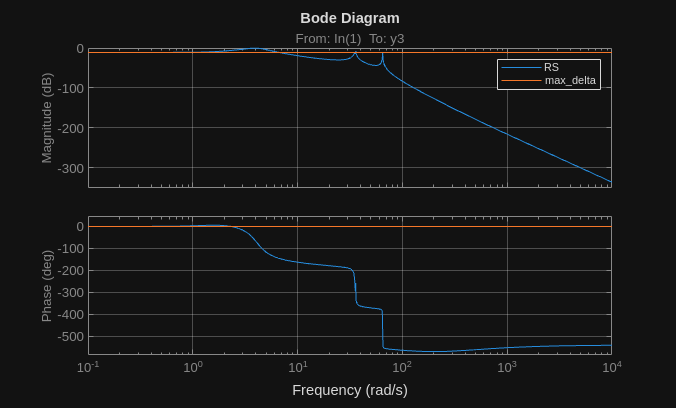

RS = T_reduced*max_delta;
bode(RS, max_delta)
grid on
legend()

## Question 14

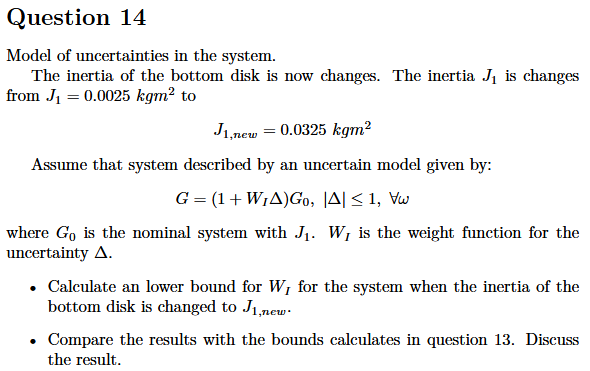

J_1new = 0.0325;
J_1 = J_1new;
syms f_theta1 f_theta2 f_theta3 f_u1 f_u2 theta1 omega1 theta2 omega2 theta3 omega3
syms u1 u2 y1 y2 y3 %b_1 b_2 b_3 J_1 k_1 k_2
x = [theta1 omega1 theta2 omega2 theta3 omega3].';
u = [u1 u2].';
y = [y1 y2 y3].';
f = [f_theta1 f_theta2 f_theta3 f_u1 f_u2].';
A = [0, 1, 0, 0, 0, 0;
     -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0;
     0, 0, 0, 1, 0, 0;
     k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0;
     0, 0, 0, 0, 0, 1;
     0, 0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];
B = [0 0
     1/J_1 0
     0 0
     0 1/J_1
     0 0
     0 0];
C = [1 0 0 0 0 0
     0 0 1 0 0 0
     0 0 0 0 1 0];
D = [0];
E_x = [0 -1/J_1 0 0 0 0].';
E_x2 = [0 0 0 0 0 0].';
E_y = zeros(3,1);
F_x = [zeros(6, 3), B];
F_y = [eye(3) zeros(3, 2)];

ThreeDiskSystem = ss(A,B,C,D);
ThreeDiskSystem.InputName = {'u1';'u2'};
ThreeDiskSystem.OutputName = {'y1';'y2';'y3'};

G = ThreeDiskSystem('y3', 'u1');

## Question 15

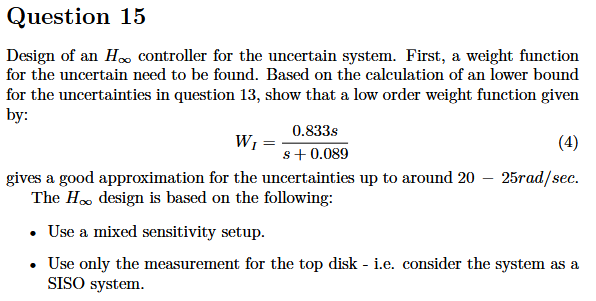

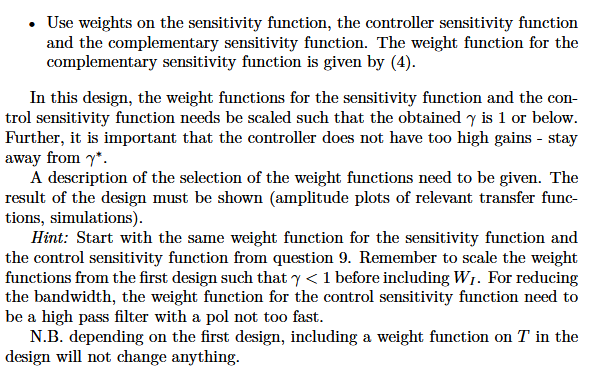

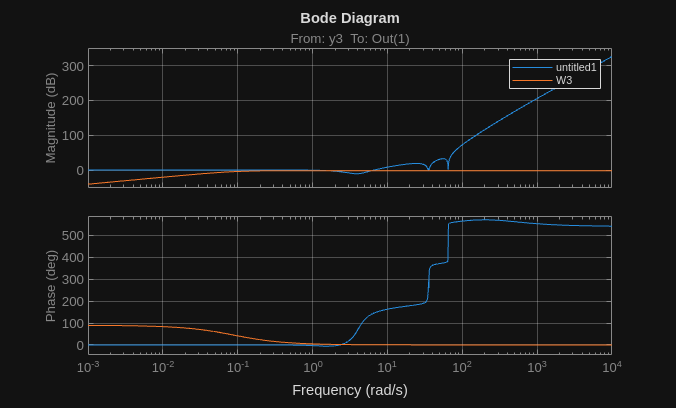

s = tf('s');

response = 1.5;
omegaB = 4/response;
M = 4;
A = 1.4^-2;

W1 = (s/M+omegaB)/(s+omegaB*A);
W2 = (s)/(s+20);
W3 = 0.833*s / (s + 0.089);

bode(1/T_reduced, W3)
grid on
legend()

[~, ~, gamma] = mixsyn(G, W1^3, W2, []);
disp(gamma)

    0.4832



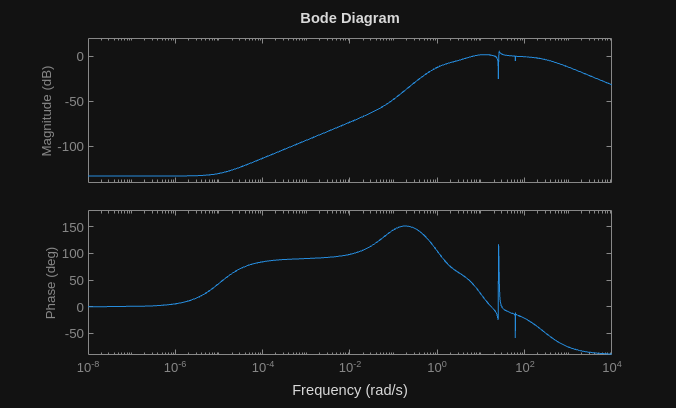

[K_uncertain, ~, gamma_uncertain] = mixsyn(G, W1^3, W2, W3);
bode(K_uncertain)

disp(gamma_uncertain)

    0.9684



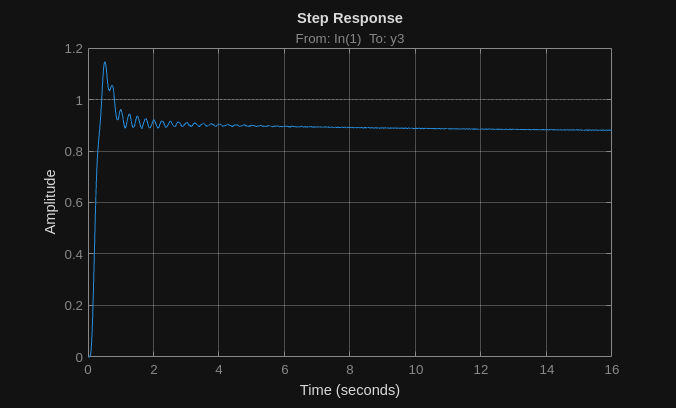

T_final = feedback(G*K_uncertain, 1);
step(T_final)
grid on

## Question 16